clc
clear
clf

%% Model Parameters
m_r = 0.082;
m_w = 0.002;
l_r = 0.35;
m_p = 0.084;
COMp = (m_r*(l_r/2)+ m_w*l_r)/(m_r + m_w);
l= COMp;
I1 = (1/3)*m_p*l^2 ;  % I med l

%% Constants
M = 0.5;
m_p = 0.084;
b_c = 5;
b_p = 0.0012;
g = 9.82;
l = 0.1792;
I = (1/3)*m_p*(0.35^2);  % I med 2l

% State space model
A = [0 1 0 0; 0 -b_c/(M+(m_p*I)/(m_p*l^2+I)) (m_p^2*l^2*g)/(M*(m_p*l^2+I)+m_p*I) (m_p*l*b_p)/(M*(m_p*l^2+I)+m_p*I); 0 0 0 1; 0 -(m_p*l*b_c)/(I*(M+m_p)+M*m_p*l^2) (m_p*g*l*(M+m_p))/(I*(M+m_p)+M*m_p*l^2) -(b_p*(M+m_p))/(I*(M+m_p)+M*m_p*l^2)]

A =          0    1.0000         0         0
         0   -9.1404    0.6638    0.0054
         0         0         0    1.0000
         0  -22.4545   25.7547   -0.2091


B = [0; 1/(M+(m_p*I)/(m_p*l^2+I)); 0; (m_p*l)/(I*(M+m_p)+M*m_p*l^2)]

B =          0
    1.8281
         0
    4.4909


C = [1 0 0 0; 0 0 1 0]

C =      1     0     0     0
     0     0     1     0


D = [0; 0];

% Converting state space to transfer functions
%rank = rank(ctrb(A,B));
s = tf('s');
sys = ss(A,B,C,D);
tfCart = minreal(tf(sys(1)));
tfPendulum = minreal(tf(sys(2)));

% Controller Variables
%Pendlum
Kp = 366.069991564719;
Ti = 3701.82722683723;
Td = 8.8851655469107;
N = 1126.11038715991;

%Cart
Kpc = -843.8063316859;
Tic = -200.862441767316;
Tdc = 59.7349659468271;
Nc = 8.95379916090364;

% PID Controller Cart
%KpidC = 1 + 1/(Tic*s) + (Tdc*s)/(1+s*(Tdc/Nc));
KpidC = pid(Kpc, Tic, Tdc, Nc);
[KpidC2, info] = pidtune(tfCart, 'PIDF')

KpidC2 =
 
             1            s    
  Kp + Ki * --- + Kd * --------
             s          Tf*s+1 

  with Kp = 4.96e+06, Ki = 1.63e+09, Kd = 3.71e+03, Tf = 2.63e-05
 
Continuous-time PIDF controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 6.9659e+03
           PhaseMargin: 68.9954


%KpidC = Kpc + Tic * 1/s + Tdc * s/((Tdc/Nc)*s+1);

% PID Controller Pendulum
%KpidP = 1 + 1/(Ti*s) + (Td*s)/(1+s*(Td/N));
KpidP = pid(Kp, Ti, Td, N);
[KpidP2, info] = pidtune(tfPendulum, 'PIDF')

KpidP2 =
 
             1            s    
  Kp + Ki * --- + Kd * --------
             s          Tf*s+1 

  with Kp = 467, Ki = 3.06e+03, Kd = 15.2, Tf = 0.0013
 
Continuous-time PIDF controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 73.1545
           PhaseMargin: 68.9954


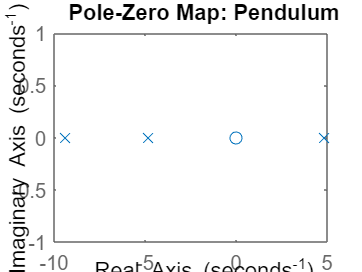

%KpidP = Kp + Ti * 1/s + Td * s/((Td/N)*s+1);

% Pole zero maps of the different transfer functions
[p,z] = pzmap(tfPendulum);
pzplot(tfPendulum);
title('Pole-Zero Map: Pendulum');

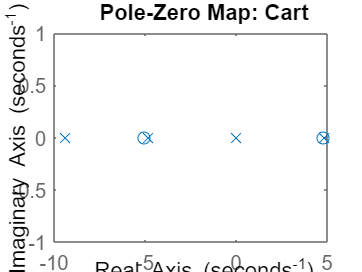

[p,z] = pzmap(tfCart);
pzplot(tfCart);
title('Pole-Zero Map: Cart');

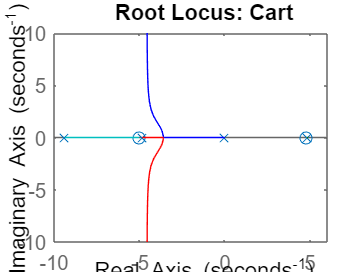


%% Root locus plots of the transferfunctions
rlocus(tfCart);
title('Root Locus: Cart');

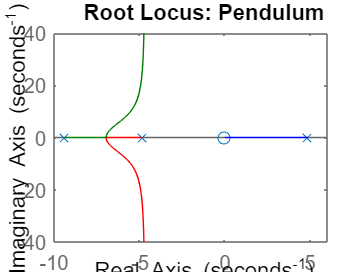

rlocus(tfPendulum);
title('Root Locus: Pendulum');

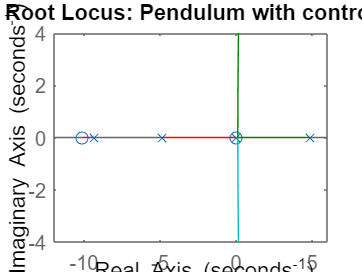

%% Root locus of the transferfunctions with controller
rlocus(KpidP * tfPendulum);
title('Root Locus: Pendulum with controller');

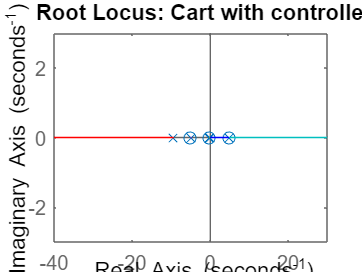

rlocus(KpidC * tfCart);
title('Root Locus: Cart with controller');

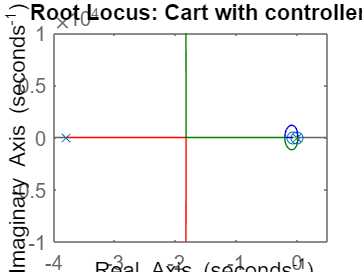

%% Root locus af PIDTUNE
rlocus(KpidC2 * tfCart);
title('Root Locus: Cart with controller2');

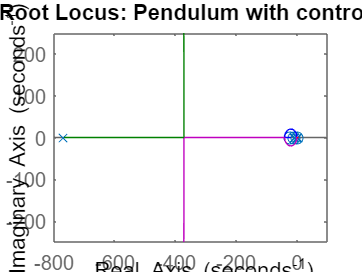

rlocus(KpidP2 * tfPendulum);
title('Root Locus: Pendulum with controller2');

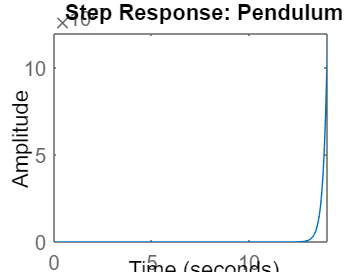


%% Step response for the system
step(tfPendulum);
title('Step Response: Pendulum');

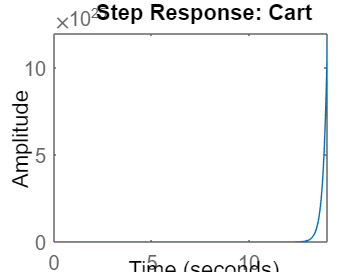

step(tfCart);
title('Step Response: Cart');

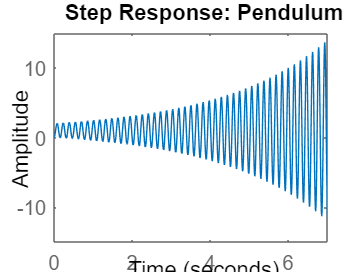

%% Step response for the system with controller
%K = Kp * KpidP;
%G1 = (K * tfPendulum) / (1 + K * tfPendulum)
G1 = (KpidP * tfPendulum) / (1 + KpidP * tfPendulum);
step(G1)
title('Step Response: Pendulum');

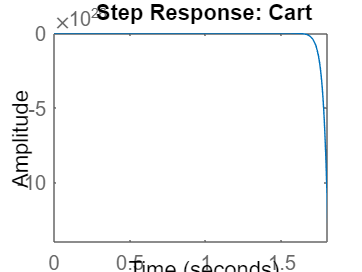

%K2 = Kpc * KpidC;
%G2 = (K2 * tfCart) / (1 + K2 * tfCart)
G2 = (KpidC * tfCart) / (1 + KpidC * tfCart);
step(G2);
title('Step Response: Cart');

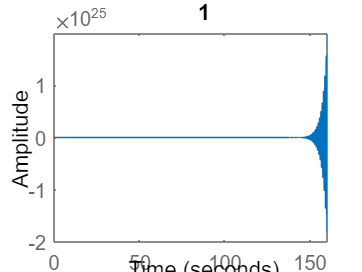

Tp = feedback(KpidP*tfPendulum, 1);
Tc = feedback(KpidC*tfCart,1);
step(Tp);
title('1');

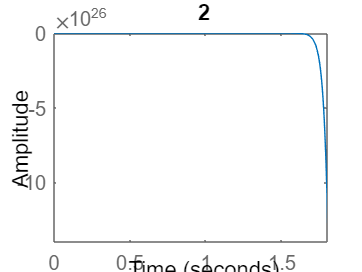

step(Tc);
title('2');

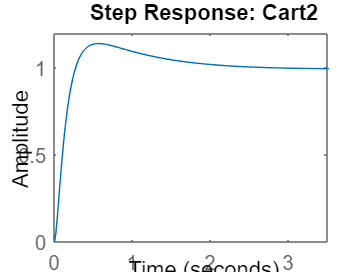



%% Step response for PIDTUNE
Gpid = KpidC2 * tfCart;
Tc2 = feedback(Gpid,1);
step(Tc2);
title('Step Response: Cart2');

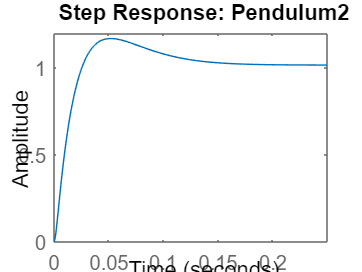

GpidP = KpidP2 * tfPendulum;
Tp2 = feedback(GpidP,1);
step(Tp2);
title('Step Response: Pendulum2');

Cascade control:

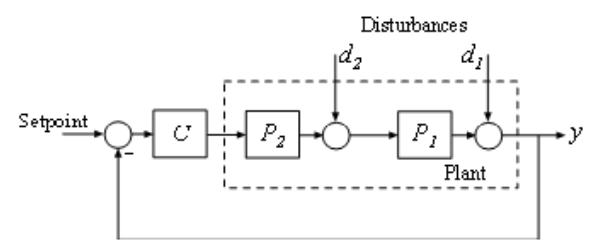

G = tfCart * tfPendulum;
Ccasc = pidstd(Kp,Ti,Td,N);
Ccasc = pidtune(G,Ccasc,0.2);

Ccasc

Ccasc =
 
             1      1              s      
  Kp * (1 + ---- * --- + Td * ------------)
             Ti     s          (Td/N)*s+1 

  with Kp = -6.46, Ti = 857, Td = 190, N = 4.35e+03
 
Continuous-time PIDF controller in standard form




% First parameter is P2.
C2 = pidtune(tfCart,pidstd(Kp,Ti,Td,N),2);
C2

C2 =
 
             1      1              s      
  Kp * (1 + ---- * --- + Td * ------------)
             Ti     s          (Td/N)*s+1 

  with Kp = -0.269, Ti = 85.7, Td = 19, N = 4.35e+03
 
Continuous-time PIDF controller in standard form




% Makes the inner closed loop. Second parameter is feedback gain
clsys = feedback(tfCart*C2,1); 

% Plant seen by the outer loop controller C1 is clsys*P1
C1 = pidtune(clsys*tfPendulum,pidstd(Kp,Ti,Td,N),0.2);

C1

C1 =
 
             1      1              s      
  Kp * (1 + ---- * --- + Td * ------------)
             Ti     s          (Td/N)*s+1 

  with Kp = 1.81, Ti = 857, Td = 190, N = 4.35e+03
 
Continuous-time PIDF controller in standard form



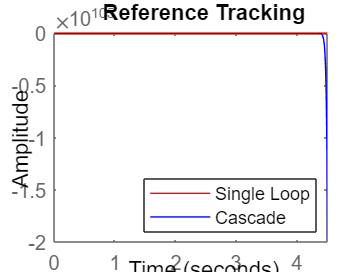


% single loop system for reference tracking 
sys1 = feedback(G*Ccasc,1);
sys1.Name = 'Single Loop';

% cascade system for reference tracking
sys2 = feedback(clsys*tfPendulum*C1,1); 
sys2.Name = 'Cascade';

% plot step response
figure;
step(sys1,'r',sys2,'b')
legend('show','location','southeast')
title('Reference Tracking')

modern controller

%% controlability & observability
% controllability
controlMatrix = ctrb(A,B);
rank(controlMatrix);
determindCon= det(controlMatrix);

% observability
observeMatrix = obsv(A,C);
rank(observeMatrix);
%determindObs= det(observeMatrix);

%%  feedback gain F og observer L
n = size(A,1); % Amount of tilstand(anatal række af A)
m = size(B,2); %amount of input (antal søjle af B)

% For integral control
% Since we only measure one output, theta, we redefine C, to make integral
% control on that. It is not possible to make integral control over both
% theta and cart position at once.

Ci = [1 0 0 0];% 0 0 1 0] 
Di = [0;0];
pint = size(Ci,1); % Amount of output(antal rækk ei c matrix)
%% Integral action
Ae = [A zeros(n,pint);
    Ci zeros(pint,pint)]

Ae =          0    1.0000         0         0         0
         0   -9.1404    0.6638    0.0054         0
         0         0         0    1.0000         0
         0  -22.4545   25.7547   -0.2091         0
    1.0000         0         0         0         0


%Ae = [A(1,:) 0 0; A(2,:) 0 0; A(3,:) 0 0 ; A(4,:) 0 0; C(1,:) 0 0; C(2,:) 0 0]
Be = [B; zeros(pint,m) ]

Be =          0
    1.8281
         0
    4.4909
         0


Ce = [Ci zeros(pint,pint)]

Ce =      1     0     0     0     0



controlExtendMatrix = ctrb(Ae,Be);
determindConExtend = det(controlExtendMatrix);
rank(controlExtendMatrix);

observeExtendMatrix = obsv(Ae,Ce);
rank(observeExtendMatrix);
%determindObsExtend= det(observeExtendMatrix);





Ts= 1;
Alpha= 1;
Sigma= -log(Alpha/100)/Ts

Sigma = 4.6052

p_1 = [-6; -7; -8; -9; -10];
Fe = -place(Ae,Be,p_1)

Fe =   449.0347  150.9397 -343.1255  -68.2672  685.7056



% For obsrver
C = [1 0 0 0; 0 0 1 0]

C =      1     0     0     0
     0     0     1     0


D = [0;0];
p_2 = [-6; -7; -8; -9]  

p_2 =     -6
    -7
    -8
    -9


P_obs= p_2*5        

P_obs =    -30
   -35
   -40
   -45


L= -place(A',Ci',P_obs)'

L = 1.0e+06 *

   -0.0001
   -0.0071
   -0.2891
   -3.0477



F= Fe(1, 1:4)

F =   449.0347  150.9397 -343.1255  -68.2672


Fi = Fe(1, 5)

Fi = 685.7056